# Son 3: Enregistrement de voix humaine et musique

sub 3

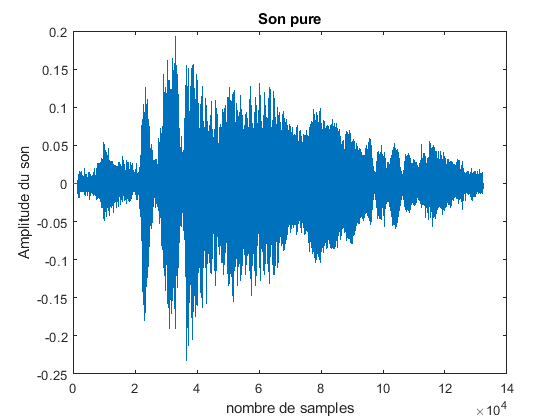

%% Exemple avec un signal de voix et musique 


clear all;
close all;
clc;
format short eng


used_time = 3; % temps en secondes

delay_time = 34 ;% temps en delais en [s] laisser écouler x secs avant échantillionnage
frequencyLimits = [0 24000]; % [Hz]   Seuil de l'audition humaine approx

%% Extraction du signal

% [son_3_sans_perturbation,sampleRate] = audioread('raspoutine.mp4'); Used to
% exctract sampleRate from original file

% sampleRate est statique a 44100 et sera donc declare de facon staique
sampleRate = 44100;
%time_total = (length(son_3_sans_perturbation)/ sampleRate); % temps en secondes

delay_points = delay_time*sampleRate;

cropped_sound = audioread('The Sound of Silence - Simon & Garfunkel.mp3',[(1+delay_points) (sampleRate*used_time+delay_points)]);

sample_point=1:1:length(cropped_sound);
%% ajout du bruit gaussien
range = 200;
SNR = 0; % signal-to-noise ratio


% Le son sera perturbé deux fois afin d'augmenter la quantité de bruit 
son_3_avec_perturbation = awgn(cropped_sound, SNR,  'measured');
son_3_avec_perturbation = awgn(son_3_avec_perturbation, SNR,  'measured');


audiowrite('sub2\son_3_avec_perturbation.wav',son_3_avec_perturbation,sampleRate);
%sound(cropped_sound,sampleRate); % ecouter son sans perturbation

audiowrite('sub2\cropped_sound.wav',cropped_sound,sampleRate);
%% Plots PURE sans perturbation
figure
plot(sample_point,cropped_sound(:,1));
title('Son pure')
xlabel('nombre de samples')
ylabel('Amplitude du son')

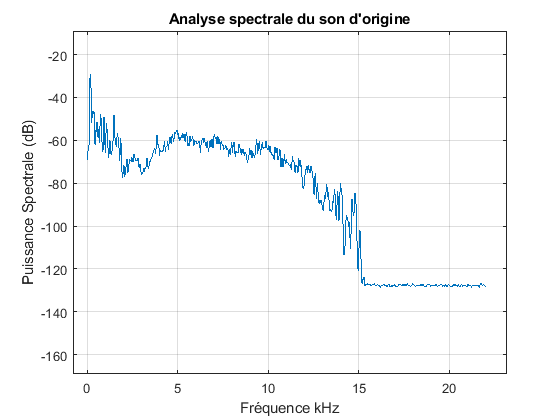



figure
SpectralAnalyser(cropped_sound(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale du son d''origine')

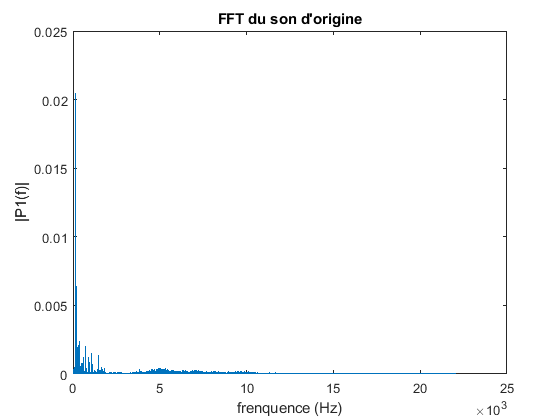


figure
fftPlotter(cropped_sound(:,1),sampleRate);
title('FFT du son d''origine')

## Plots avec perturbation

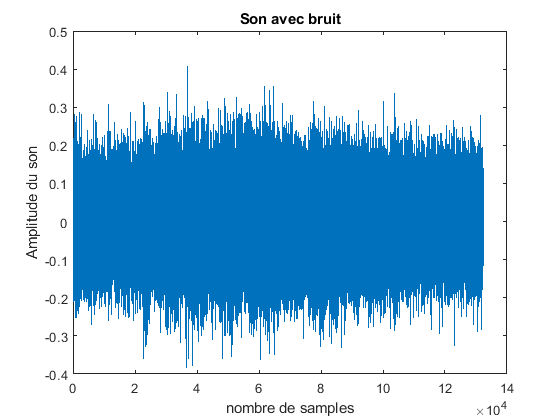


figure
plot(sample_point,son_3_avec_perturbation(:,1));
title('Son avec bruit')
xlabel('nombre de samples')
ylabel('Amplitude du son')

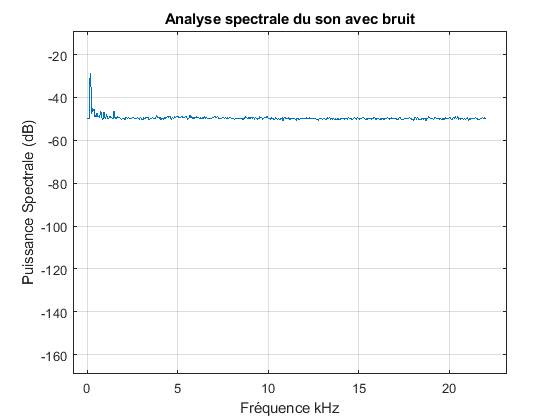


figure
SpectralAnalyser(son_3_avec_perturbation(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale du son avec bruit')

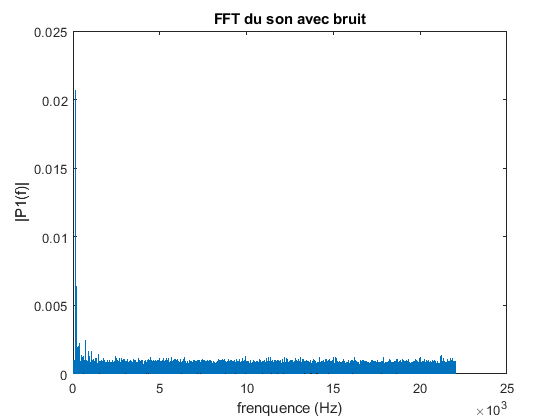


fftPlotter(son_3_avec_perturbation(:,1),sampleRate)
title('FFT du son avec bruit')


%sound(son_3_avec_perturbation,sampleRate);

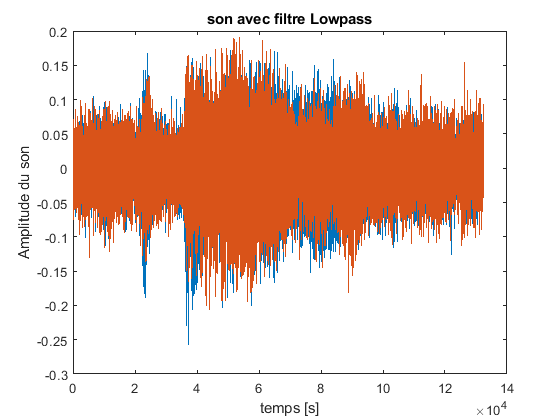



%% Application d'un filtre simple (lowpass)
freq_coupure_lowpasse = 1300; % les frequences de coupures sont determin/es a partir de la FFT

son_3_filtre_lowpass = lowpass(son_3_avec_perturbation,freq_coupure_lowpasse,sampleRate);

figure
plot(sample_point,son_3_filtre_lowpass)
title('son avec filtre Lowpass')
xlabel('temps [s]')
ylabel('Amplitude du son')

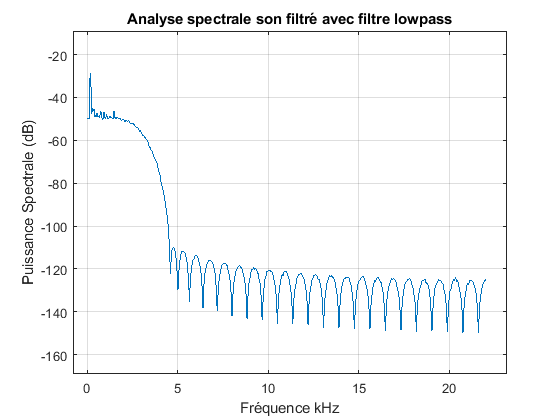


figure
SpectralAnalyser(son_3_filtre_lowpass(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale son filtré avec filtre lowpass');

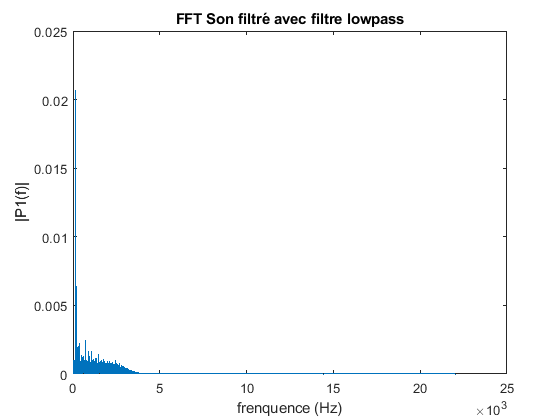


figure
fftPlotter(son_3_filtre_lowpass,sampleRate)
title('FFT Son filtré avec filtre lowpass');


%sound(son_3_filtre_lowpass,sampleRate);
audiowrite('sub2\son_3_filtre_lowpass.wav',son_3_filtre_lowpass,sampleRate);

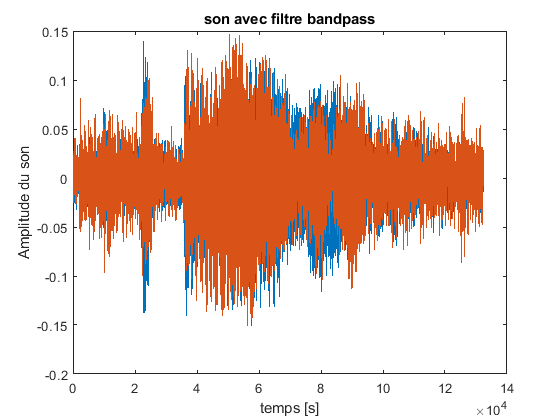

son_2_filtre_bandpass2 = bandpass(son_3_avec_perturbation,[40 600],sampleRate);

audiowrite('sub2\son_2_filtre_bandpass2.wav',son_2_filtre_bandpass2,sampleRate);


%% plot filtre bandpass

figure
plot(sample_point,son_2_filtre_bandpass2)
title('son avec filtre bandpass')
xlabel('temps [s]')
ylabel('Amplitude du son')

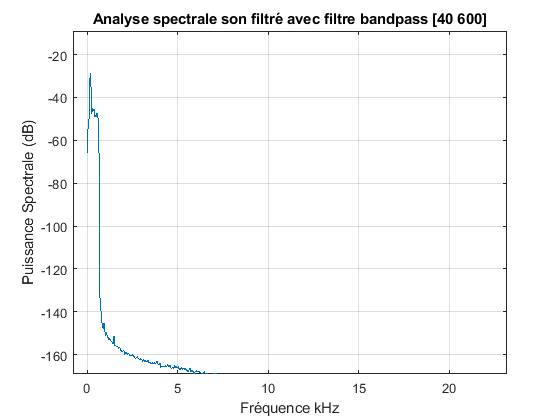


figure
SpectralAnalyser(son_2_filtre_bandpass2(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale son filtré avec filtre bandpass [40 600]');

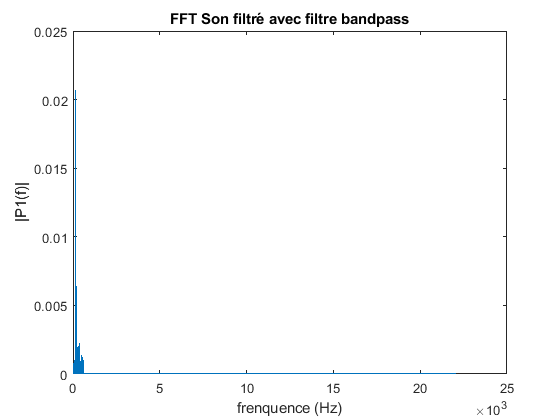


figure
fftPlotter(son_2_filtre_bandpass2,sampleRate)
title('FFT Son filtré avec filtre bandpass');

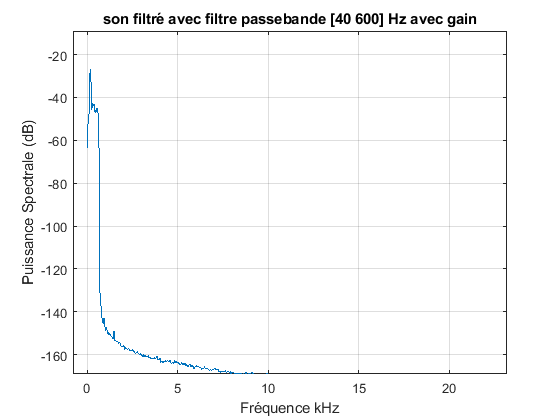

son_2_filtre_bandpass2_2 = son_2_filtre_bandpass2*1.3; % application d'un gain

figure
SpectralAnalyser(son_2_filtre_bandpass2_2,sampleRate,frequencyLimits,0,[0 15]);
title('son filtré avec filtre passebande [40 600] Hz avec gain')


%sound(son_2_filtre_bandpass2_2, sampleRate);
audiowrite('sub2\son_2_filtre_bandpass2_2.wav',son_2_filtre_bandpass2_2,sampleRate);

## Comb filter



N     = 40 ;   % Order
BW    =  1000% Bandwidth

BW =      1.0000e+003


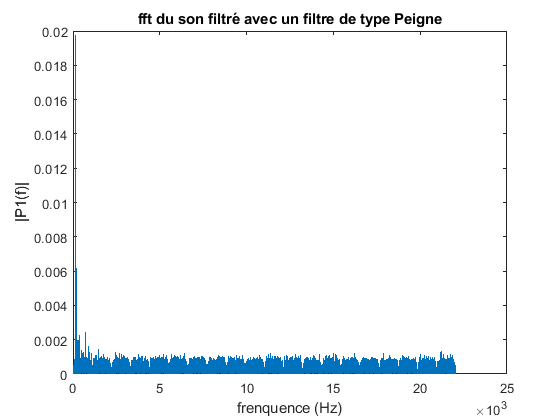

Apass = 3;    % Bandwidth Attenuation

[b, a] = iircomb(N,...
    BW/(sampleRate/2),...
    Apass, 'peak');


combFilt    = dfilt.df2(b, a);

resComb = filter(combFilt,son_3_avec_perturbation);
figure
fftPlotter(resComb,sampleRate);
title('fft du son filtré avec un filtre de type Peigne')

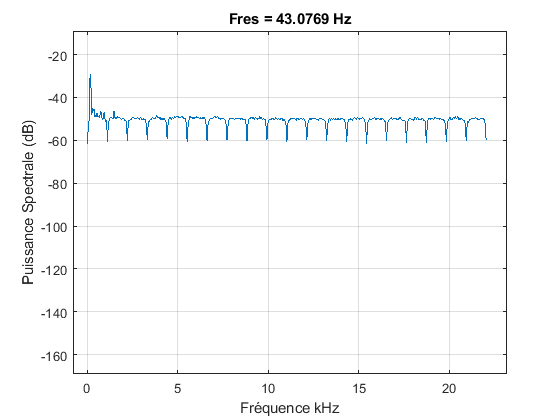


SpectralAnalyser(resComb(:,1),sampleRate,frequencyLimits,0,[0 15]);


%sound(resComb,sampleRate);
audiowrite('sub2\resComb.wav',resComb,sampleRate);


## Application d'un filtre Chebychev

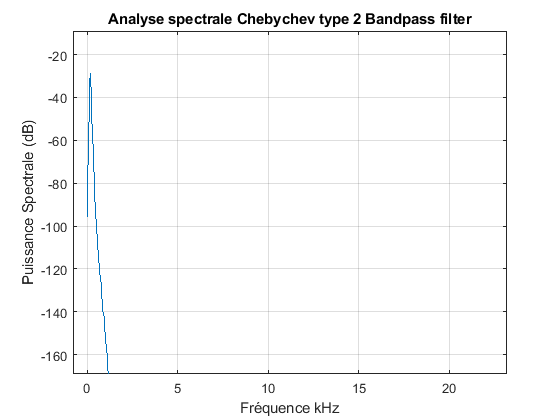

   
Fstop1 = 15;  % First Stopband Frequency
Fstop2 = 1200;  % Second Stopband Frequency
Astop  = 130;   % Stopband Attenuation (dB)
filtOrder = 12; % Order

% Construct an FDESIGN object and call its CHEBY2 method.
h  = fdesign.bandpass('N,Fst1,Fst2,Ast', filtOrder, Fstop1, Fstop2, Astop, sampleRate);
cheby2 = design(h, 'cheby2');

resCheb = filter(cheby2,son_3_avec_perturbation);

figure
SpectralAnalyser(resCheb,sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale Chebychev type 2 Bandpass filter')

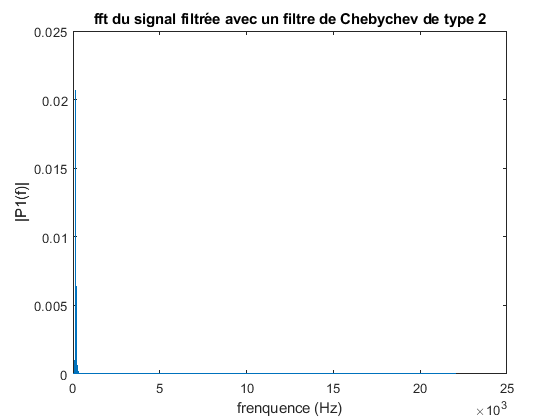

%xlim([0 20])
%ylim([-120 24])


%sound(resCheb,sampleRate);
audiowrite('sub2\resCheb.wav',resCheb,sampleRate);
figure
fftPlotter(resCheb,sampleRate)
title('fft du signal filtrée avec un filtre de Chebychev de type 2')

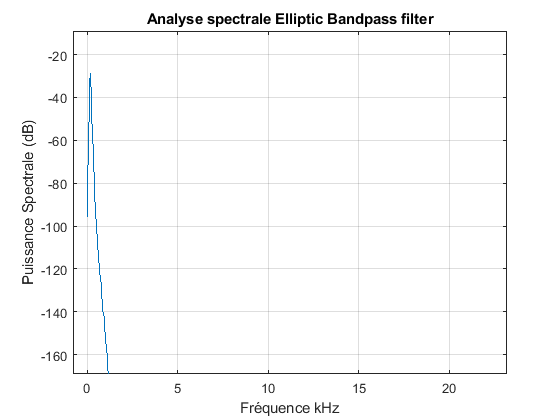

%Bandpass Elliptic Filter
%View MATLAB Command

%Design a 20th-order elliptic bandpass filter with a lower passband frequency of 500 Hz and a higher passband frequency of 560 Hz. Specify a passband ripple of 3 dB, a stopband attenuation of X dB, and a sample rate of Y Hz. Use the state-space representation. Design an identical filter using designfilt.

%[A,B,C,D] = ellip(10,3,40,[500 560]/750);
d = designfilt('bandpassiir','FilterOrder',filtOrder, ...
    'PassbandFrequency1',Fstop1,'PassbandFrequency2',Fstop2, ...
    'PassbandRipple',3, ...
    'StopbandAttenuation1',40,'StopbandAttenuation2',Astop, ...
    'SampleRate',sampleRate);

resEllip= filter(d,son_3_avec_perturbation);


figure
SpectralAnalyser(resCheb,sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale Elliptic Bandpass filter')

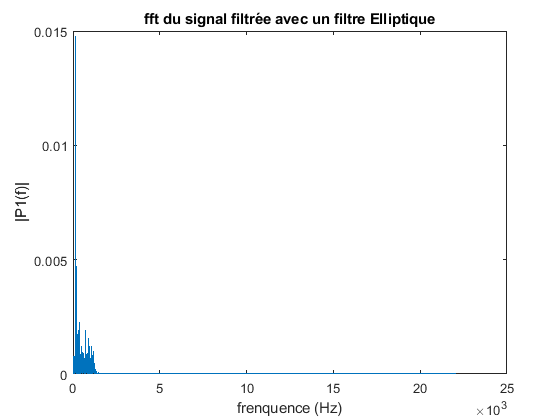



figure
fftPlotter(resEllip,sampleRate);
title('fft du signal filtrée avec un filtre Elliptique')


%sound(resEllip,sampleRate);
audiowrite('sub2\resEllip.wav',resEllip,sampleRate);


## comparing Chebychev 2 and Elliptic bandpass filters

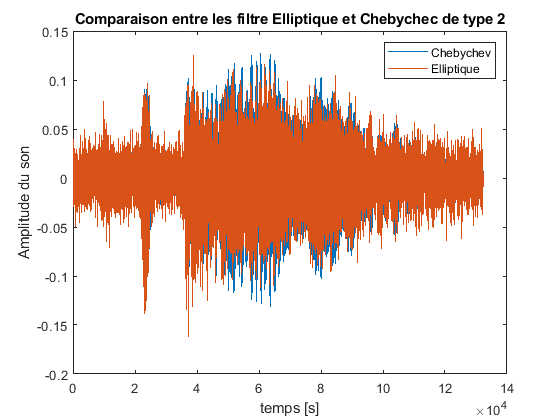

figure
plot(sample_point,resCheb(:,1));
hold on;
plot(sample_point,resEllip(:,1));
title('Comparaison entre les filtre Elliptique et Chebychec de type 2')
xlabel('temps [s]')
ylabel('Amplitude du son')
legend('Chebychev','Elliptique');
hold off;

## Wavelet analysis machine learning denoising 

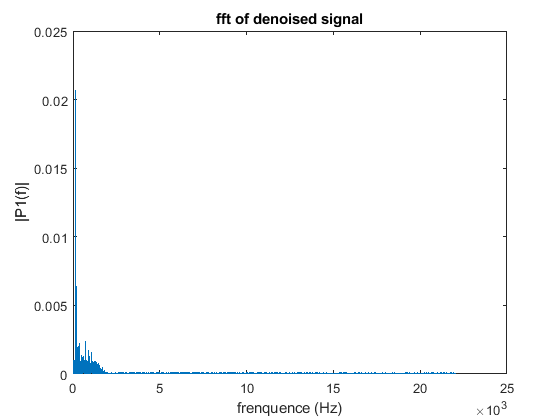

datsignal = son_3_avec_perturbation(:,1) ;


resDenoise = wdenoise(datsignal,4, ...
    'Wavelet', 'sym8', ...
    'DenoisingMethod', 'minimax',...
    'ThresholdRule', 'Hard', ...
    'NoiseEstimate', 'LevelDependent');

figure
fftPlotter(resDenoise,sampleRate);
title('fft of denoised signal')


%sound(resDenoise,sampleRate);
audiowrite('sub2\resEllip.wav',resEllip,sampleRate);